# Test 3: Multi-layered and spherically-symmetric (Io)

In this notebook the tidal response of a multi-layered, spherically-symmetric, viscoelastic body is computed using LOV3D and compared against results obtained with the [code](https://github.com/mroviranavarro/Poroviscoelastic_Tides) of [Rovira-Navarro et al. 2022](https://doi.org/10.1029/2021JE007117) ([code](https://github.com/mroviranavarro/Poroviscoelastic_Tides)) and [Beuthe et al. 2013](https://www.sciencedirect.com/science/article/pii/S0019103512004745?casa_token=xg0XfpmaHT4AAAAA:Qau6ppdURvhX_Vgm_NiDZVwEtERNnqcosVviHYGaLIHJLBugG7ZgBEnHNPG921Qc5SZAktQ6kw)

clearvars
clc
set(0,'defaulttextInterpreter','latex') 
mfile_name          = mfilename('fullpath');
if contains(mfile_name,'LiveEditorEvaluationHelper')
    mfile_name=matlab.desktop.editor.getActiveFilename;
end
[pathstr,name,ext]  = fileparts(mfile_name);
cd(pathstr);
cd('..')
addpath(genpath(pwd))

## Interior model

The interior model is based on the Io model of [Steinke et al. 2023](https://doi.org/10.1016/j.icarus.2019.05.001) and [Beuthe et al. 2013](https://www.sciencedirect.com/science/article/pii/S0019103512004745?casa_token=xg0XfpmaHT4AAAAA:Qau6ppdURvhX_Vgm_NiDZVwEtERNnqcosVviHYGaLIHJLBugG7ZgBEnHNPG921Qc5SZAktQ6kw), which consists on a core, mantle, asthenosphere and lithosphere. Three different interior models are considered

- Interior Model A: Tidal heating only occurs in the asthenosphere (based on [Steinke et al. 2023](https://doi.org/10.1016/j.icarus.2019.05.001) ) 

- Interior Model B: Tidal heating occurs in both asthenosphere and deep mantle (based on [Steinke et al. 2023](https://doi.org/10.1016/j.icarus.2019.05.001))

- Interior Model C: Tidal heating occurs in both layers (based on  [Beuthe et al. 2013](https://www.sciencedirect.com/science/article/pii/S0019103512004745?casa_token=xg0XfpmaHT4AAAAA:Qau6ppdURvhX_Vgm_NiDZVwEtERNnqcosVviHYGaLIHJLBugG7ZgBEnHNPG921Qc5SZAktQ6kw))

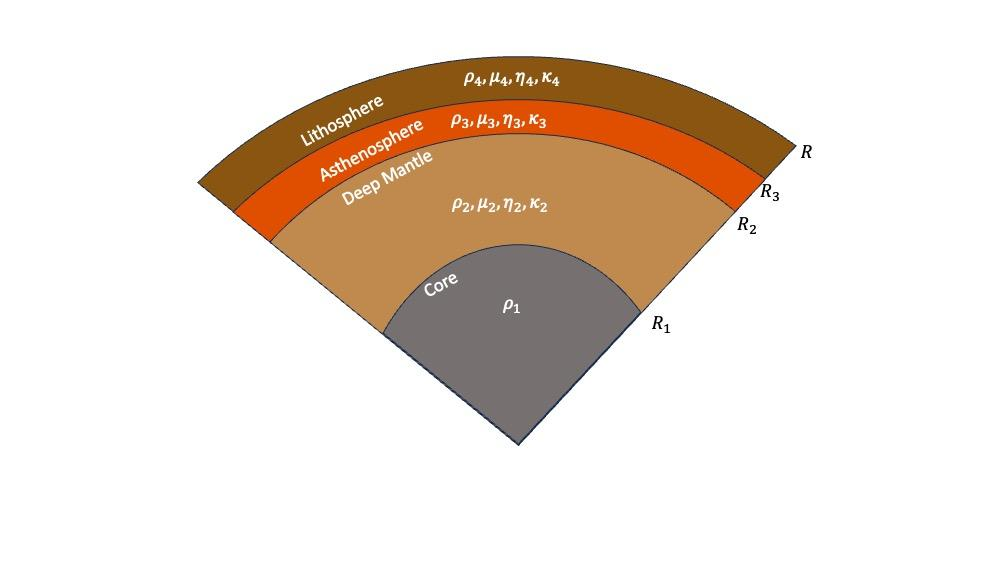

The model parameters are given in dimensional form 

% Values are taken from Steinke et al. (2020a)
T=87.969*24*3600; %Mercury's orbital period


% Interior model A, asthenosphere only heating 
% Interior_Model goes from core (1) to surface (n) with indices

% needto replace layer 1 with solid inner core
% Interior_Model_A(1)

% Interior_Model values for the inner, solid core
Interior_Model_A(1).R0 = 1000; % inner core radius
Interior_Model_A(1).rho0 = 7211.; % average density in kg m^-3
Interior_Model_A(1).rho0_2 = 5150; % rho_2 in kg m^-3 (used for icy moons)
Interior_Model_A(1).Ks0 = 165e9;
Interior_Model_A(1).mu0 = 100e9;

% Interior_Model values for outer, liquid core
Interior_Model_A(2).R0 = 2000.; % cmb radius
Interior_Model_A(2).rho0 = 7019.; % density in kg m^-3
Interior_Model_A(2).Ks0 = 87e9; % bulk modulus in Pa
Interior_Model_A(2).mu0 = 0.; % shear modulus in Pa
Interior_Model_A(2).eta0 = 0.; % viscosity in Pa s

% Interior_Model values for mantle
Interior_Model_A(3).R0 = 2400; % outer radius of this layer
Interior_Model_A(3).rho0 = 3380.; % density in kg m^-3
Interior_Model_A(3).Ks0 = 120e9; % bulk modulus in Pa
Interior_Model_A(3).mu0 = 65e6; % shear modulus in Pa
Interior_Model_A(3).eta0 = 1e11; % viscosity in Pa s

% Interior_Model values for crust
Interior_Model_A(4).R0 =2440; % outer radius of this layer
Interior_Model_A(4).rho0 = 3380.; % density in kg m^-3
Interior_Model_A(4).Ks0 = 200e12; % bulk modulus in Pa
Interior_Model_A(4).mu0 = 55e9; % shear modulus in Pa (Maxwell)
Interior_Model_A(4).eta0 = 1e23; % viscosity in Pa s (Maxwell)

## Define forcing

The forcing potential is defined

Forcing(1).Td=T;
Forcing(1).n=2; 
Forcing(1).m=0; 
Forcing(1).F=1;

## Define numerics used to compute the tidal response 

%radial discretization
Numerics.Nlayers = length(Interior_Model_A); % number of concentric layers. Including the core!
Numerics.method = 'variable'; % method of setting the radial points per layer, here fixed number of layers
Numerics.Nrbase = 2000; % depending on the method this will determine the number of points per layer
%code parallelization
Numerics.parallel_sol = 0; % Use a parfor-loop to call get_Love, either 0 or 1
Numerics.parallel_gen = 0; % Calculate potential coupling files and the propagation inside get_solution using parfor-loops, either 0 or 1
% lateral variations
Numerics.perturbation_order = 2; %maximum order to which couplings are considered
Numerics.solution_cutoff = 12; % maximum degree of solution, not used if perturbation order is specified
Numerics.load_couplings = 1; % 0=no loading, 1=loading of specific file, 2=searches for big enough file
Numerics.Nenergy = 12; % maximum degree to which energy dissipation is expanded 
Numerics.rheology_cutoff = 2; % maximum order of difference (so in log) up to which rheology is still used 
[Numerics, Interior_Model_A] = set_boundary_indices(Numerics, Interior_Model_A,'verbose');

Inside set_boundary_indices: 
Nrlayer: 0  2000  2000  2000
BCindices: 2001  4001  6001
Nr: 6000
 


## Compute the tidal response 

The tidal response is obtained for models A and B 

% write interior model in the right format for the code
Interior_Model_A= get_rheology(Interior_Model_A,Numerics,Forcing);

No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 3, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 4, I will assume the layer is spherically-symmetric 


% Interior_Model_B= get_rheology(Interior_Model_B,Numerics,Forcing);
% Interior_Model_C= get_rheology(Interior_Model_C,Numerics,Forcing);
[Love_Spectra_A,y_A]=get_Love(Interior_Model_A,Forcing,Numerics,'verbose');

Obtaining Couplings....
Only uniform layers so coupling matrix is zero
------------- INTERIOR MODEL ----------- 
AVERAGE PROPERTIES (dimensional)
Layer#     R[m]    rho[kg.m^{-3}]    mu[Pa]    K[Pa]    eta[Pa.s]
1    1.00000e+03    7.21100e+03    0    -
2    2.00000e+03    7.01900e+03    0.00000e+00    8.70000e+10 0.00000e+00
3    2.40000e+03    3.38000e+03    6.50000e+07    1.20000e+11 1.00000e+11
4    2.44000e+03    3.38000e+03    5.50000e+10    2.00000e+14 1.00000e+23
AVERAGE PROPERTIES (non-dimensional)
Layer#     R[-]    rho[-]    mu[-]    K [-]     eta[-]
1    0.40984    2.1334    0    -
2    0.81967    2.0766    0    1.5818 0
3    0.98361    1    0.0011818    2.1818 2.3922e-07
4    1    1    1    3636.3636 239218.0318
RHEOLOGY  VARIATIONS
Shear Modulus
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
2    (0,0)   0.00000e+00
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
3    (0,0)   0.00000e+00
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
4   

% [Love_Spectra_B,y_B]=get_Love(Interior_Model_B,Forcing,Numerics,'verbose');
% [Love_Spectra_C,y_C]=get_Love(Interior_Model_C,Forcing,Numerics,'verbose');


## Comparison of k2 Love numbers

The values obtained with the spherically-symmetric poroviscoealstic [code](https://github.com/mroviranavarro/Poroviscoelastic_Tides) are: 

- Model A: 0.733721707307109 - 0.015123675091503i

- Model B: 0.611841605660674 - 0.015009557001099i

- Model C: should lead to -Im(k2)=0.015 as stated in [Beuthe et al. 2013](https://www.sciencedirect.com/science/article/pii/S0019103512004745?casa_token=xg0XfpmaHT4AAAAA:Qau6ppdURvhX_Vgm_NiDZVwEtERNnqcosVviHYGaLIHJLBugG7ZgBEnHNPG921Qc5SZAktQ6kw)

disp(['k_2 Model A ' num2str(Love_Spectra_A.k)])
% disp(['k_2 Model B ' num2str(Love_Spectra_B.k)])
% disp(['k_2 Model C' num2str(Love_Spectra_C.k)])